load("src\zadanie_06.mat")

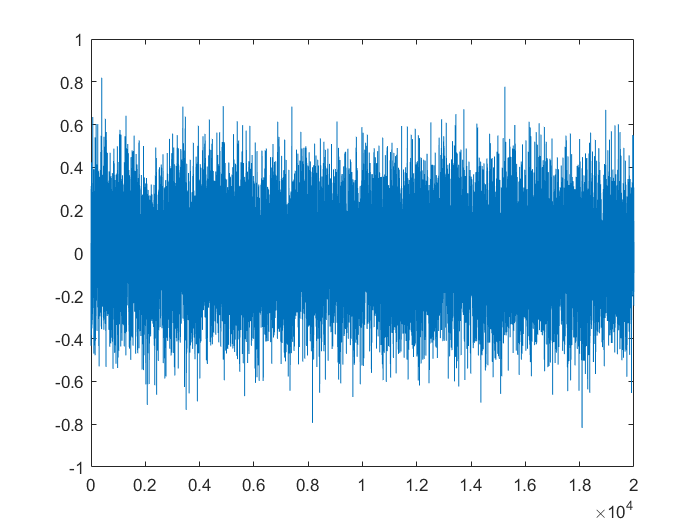

figure
plot(y)

th1 = 0.1:0.1:4;
th2 = 0.1:0.1:4;
th = [th1; th2]

th =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000
    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000


th_test = th(:, 1)

th_test =     0.1000
    0.1000


q = l_fun(th_test, y, A, B, G, C)

q = -0.2135

handle = @l_fun

handle = function_handle with value:
    @l_fun


function q=l_fun(th, y, A, B, G, C)

[nx, ~] = size(A);
N = length(y);
th = th.^2;
q = 0;
m = zeros(nx, 1);
S = zeros(nx, nx);
u = 0;
for k = 1:N - 1
   m = A*m + B*u;
   S = A*S*A' + (G*G') * th(1);
   W = th(2) + C*S*C';
   e = y(k + 1) - C*m;
   q = (k - 1) * q/k + (e*e/W + log(W))/k;
   S = S - (S*(C' * C)*S)/W;
   m = m+S*C'*e/th(2);
end
q = 0.5 * q;

end